1.  Simulate the linear dynamical system using dynamo4x.m (slides 35 and 36) given by the matrix M= [[-1 2];[-1 -2]].   How would you describe the equilibrium point?

% M=[[-1 2];[-1 -2]];
% figure
% dynamo4x(-3:.1:3,.02,1000,M,[0 0]')

2.  Repeat by using a new matrix that is -**M**.  How is it different?

% figure
% dynamo4x(-3:.1:3,.02,1000,-M,[0 0]')

3.  Fit a second order polynomial to the data points (0,0, (0.1,1), and (1,1).  Plot the result and compare this to a linear fit (1st order polynomial).

clear;
xinfo = [0 0.1 1];
yinfo = [0 1 1];
figure
scatter(xinfo,yinfo,200,"filled")
hold on
x_vals=linspace(0,1,20);
p2=polyfit(xinfo,yinfo,2)

p2 =   -10.0000   11.0000   -0.0000


y_vals=polyval(p2,x_vals);
plot(x_vals,y_vals)
p1=polyfit(xinfo,yinfo,1)

p1 =     0.6044    0.4451


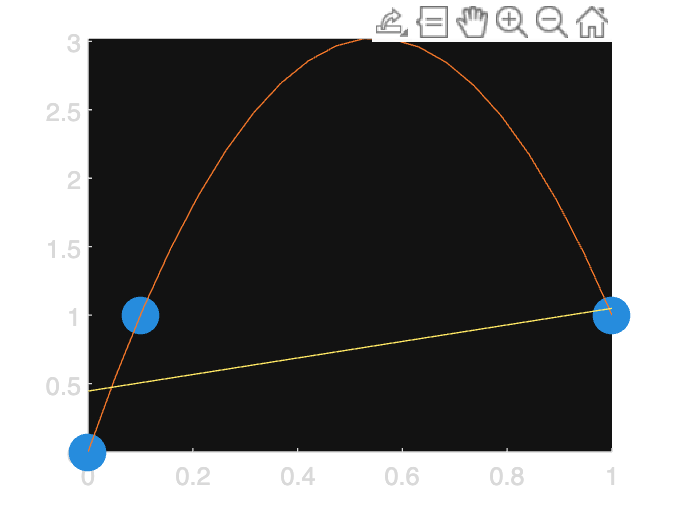

y_vals=polyval(p1,x_vals);
plot(x_vals,y_vals)  

Functions from slides

function ptseq = dynamo4x( rang,step,niter,cmtx,cvct )
figure
xinit=[rang rang rang(1)*ones(size(rang)) rang(end)*ones(size(rang))];
yinit=[rang(1)*ones(size(rang)) rang(end)*ones(size(rang)) rang rang];
[xcr,ycr] = meshgrid(linspace(rang(1),rang(end),100));
nullx=cmtx(1,1)*xcr+cmtx(1,2)*ycr+cvct(1,1);
nully=cmtx(2,1)*xcr+cmtx(2,2)*ycr+cvct(2,1);
% size(xinit)
for k=1:max(size(xinit))
    ptseq=[xinit(k);yinit(k)] ;
    curr=[xinit(k);yinit(k)] ;
    for i=1:niter
        curr=onestep(curr,cmtx,cvct,step) ;
        ptseq=[ptseq,curr] ;
    end
    plot(ptseq(1,:),ptseq(2,:),'blue')
    axis equal
    hold on ;
end
axis([rang(1) rang(end) rang(1) rang(end)])
contour(xcr,ycr,nullx,[0 0],'red','LineWidth',2) ;
contour(xcr,ycr,nully,[0 0],'red','LineWidth',2) ;
qplot(cmtx,cvct,rang(1):.5:rang(end))
end


function newx = onestep(oldx,cmat,cvec,dt)
newx=oldx+(cmat*oldx+cvec)*dt ;
end


function qv = qplot( cmat,cvec,rang )
%This function generates a quiver plot for the linear system
%specified by cmat. rang is the range (for both x and y)
[xx, yy] = meshgrid(rang) ;
qv=[] ;
for xp=rang
    tcol=[] ;
    for yp=rang
        temp=.1*(cmat*[xp yp]'+cvec) ;
        tcol=[tcol,temp] ;
    end
    qv=cat(3,qv,tcol) ;
end
qx=reshape(qv(1,:,:),size(xx,1),size(xx,2)) ;
qy=reshape(qv(2,:,:),size(yy,1),size(yy,2)) ;
quiver(xx,yy,qx,qy,'black') ;
axis equal
axis([[rang(1) rang(end)],[rang(1) rang(end)]]) ;
end


function [pfinal, xpow] = gdpoly( xx, yy, pinit, niter, eta )
% gradient descent in a polynomial function
%   dak/dt = 2(y*-y)x^k
nn=max(size(pinit)) ;
kk=max(size(xx)) ;

xmin=min(xx)-.1*(max(xx)-min(xx)) ;
xmax=max(xx)+.1*(max(xx)-min(xx)) ;
ymin=min(yy)-.1*(max(yy)-min(yy)) ;
ymax=max(yy)+.1*(max(yy)-min(yy)) ;
xstep=.02*(xmax-xmin) ;
xvals=xmin:xstep:xmax ;
xpow=ones(kk,1) ;
for ii=2:nn
    xpow=[xx'.*xpow(:,1),xpow] ;
end
pfinal=pinit ;
figure
h1=scatter(xx,yy,250,'red','filled') ;
hold on
yest=polyval(pfinal,xvals) ;
h2=plot(xvals,yest) ;
axis([xmin xmax ymin ymax]) ;
for ii=1:niter
    datapt=irand(kk,1) ;
    yest=polyval(pfinal,xx(datapt)) ;
    dp=(yest-yy(datapt))*xpow(datapt,:) ;
    pfinal=pfinal - dp*eta ;
    ycurve=polyval(pfinal,xvals) ;
    set(h2,'XData',xvals,'YData',ycurve) ;
    drawnow
end
end